c = ['https://d396qusza40orc.' ...
    'cloudfront.net/digital%2Fimages%2Fweek'];
cb = '_quizzes%2F';

dec2bin(251)

ans = '11111011'

dec2bin(2^5)

ans = '100000'

dec2bin(g(1:5))

ans = 5x8 char array
    '00001110'
    '01100100'
    '10000001'
    '10000100'
    '01111001'


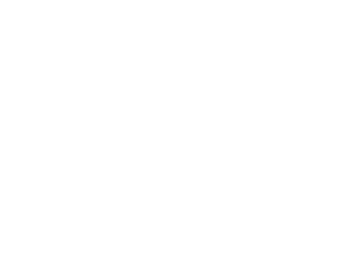

imshow(g & 2^5)

g & 2^5

ans = 512x512 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

c = cell(1,9); c{1} = g;
for r = 7:-1:0
    c{9-r} = bitand(g, 2^r)&1;
end

7:-1:0

ans =      7     6     5     4     3     2     1     0


251 & 2^5

ans = logical
   1


dec2bin(bitand(251, 2^5))

ans = '100000'

imshow(bitand(g, 2^(0:1))&1)

Error using  ^ 
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To operate on each element of the matrix individually, use POWER (.^) for elementwise power.

bitand(g, 2.^(0:1))&1

Error using bitand
Inputs must have the same size.

## bitand(g, 2^5)

{g,i}

ans = 1x2 cell array
    {512x512 uint8}    {512x512x3 uint8}


## Convert the image to data type double.

% i = [c '2' cb 'lena.gif'];
% i = [c '3' cb 'original_quiz.jpg'];
% I = im2double(imread(i));
% I = im2double(imread(i));
I1 = im2double(imread([c '4' cb 'frame_1.jpg']));
I2 = im2double(imread([c '4' cb 'frame_2.jpg']));
whos I1; whos I2; Btarget = I2(65:96,81:112);

  Name        Size              Bytes  Class     Attributes

  I1        288x352            811008  double              

  Name        Size              Bytes  Class     Attributes

  I2        288x352            811008  double              



s = 255; M = 32; N = 32;
for i = 0:N:size(I1,1)-N
    for co = 0:M:size(I1,2)-M
        v = sum(abs(I1(i+(1:M), co + (1:N ...
            )) - Btarget),"all")/M/N;
        if v <= s
            s = v; a = i + co; MAE = v;
        end
    end
end

I1(0, 0)

Index in position 1 is invalid. Array indices must be positive integers or logical values.

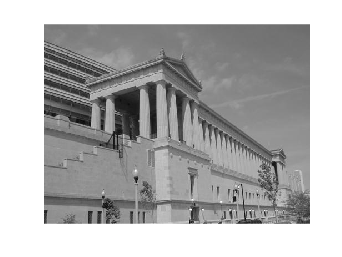

imshow(I); s = 4; % 3 = low-pass filtering, 5

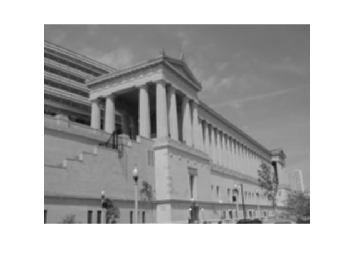

filteredRGB = imfilter(I, ones(s, s)/s^2,...
'replicate'); figure, imshow(filteredRGB);

y = filteredRGB(1:2:end, 1:2:end)

y = 180x240 uint8 matrix
   122   123   124   124   123   122   122   121   120   120   120   120   120   120   122   123   124   124   124   124   122   122   124   124   125   125   125   125   125   125   125   125   124   124   124   124   125   125   127   129   131   134   135   135   136   137   136   134   131   127
   124   124   125   124   124   122   122   121   121   120   120   120   120   120   122   123   123   124   124   123   122   122   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   126   129   131   132   132   132   133   135   135   135   132   128
   126   126   125   124   123   122   122   121   121   122   122   121   121   121   121   122   122   122   122   122   122   122   124   124   124   124   124   124   124   124   124   124   124   124   124   124   125   125   127   129   132   133   133   133   133   133   133   134   133   129
   128   127   127   126   124   123   122   121   122   123   123   122

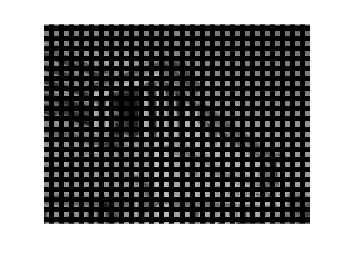

% m = zeros(359, 479)
u = upsample(upsample(y',2)',2);
c = u(1:end-1,1:end-1); figure; imshow(c)

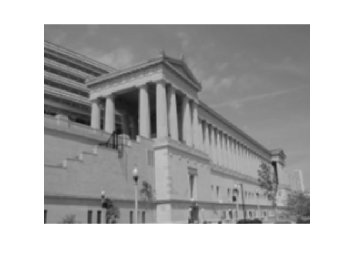

filteredRGB = imfilter(c, [0.25, 0.5, 0.25;
                           0.5, 1, 0.5;
                           0.25, 0.5, 0.25]);
% 2 arguments are the result from above step.
figure, imshow(filteredRGB);

MAXI = 255; MSE = immse(I, filteredRGB);
fprintf('\nThe mean-squarederror is %0.4f\n', MSE);


The mean-squarederror is 149.2408


PSNR=10*log10(MAXI^2/MSE)

PSNR = 26.3919

round(PSNR,2) % , where MAXI

ans = 26.3900

% is the maximum possible pixel value of the images.
% For the 8-bit gray-scale images.